# Sensitivity Analysis: Signal & Hyperparameter Selection Test File  

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 23/11/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

To test the reliability and implement the HSFP framework within a backtest that constructs both MV and HRP portfolios, we need to make 3 decisions: 

- Choosing the HS-FP method (exponential decay, entropy pooling, etc.)

- Determining the signal(s) to supply the method with

- Selecting the appropriate parameters for the method

To simplify the approach we will only consider multiple cofigurations of the last 2 points and run the configurations  for each HSFP method in turn. This is significant due to the fact that different methods require different number of signals which can complicate the code. 

This file is set up as follows: 

Section 1: Time & Single State conditioned methods 

Section 2: Multi- state & Time conditioned methods 

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

Add path to backtestedPortfolio object: 

addpath '/Users/Ninamatthews/Documents/MATLAB/STA5000W DISSERTATION Code/OOP'

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

# TEST CASE: HS-FP HYPER-PARAMETERS

# 5 data points per hyper-parameter

## 3. Set up hyper-parameter ranges (will generalise at a later stage)

Range is created for all hyper parameters that will be varied.

For the data tuning we use: 

- $\lambda$ - **Window Length** (currently 12 months [3 - 36 months] don't want more than 3 months)

- $\tau$ - **half-life for Exponential decay** (currently 12 months [3 - 36 months] )

- $z^*$-** Crisp target value** (latest time point [*varies based on signal so can't be a specifc value -can potentially create a range based on each signal (min to max) and same number of points as other parameters*)])

- $\alpha$ - **Crisp range of probability** (0.1)

- $h$ - **Kernel bandwidth **(0.5)

- $\gamma$ - **Kernel type** (2 - Gaussian [can only be 2 or 1 for exponential] )

% **Options for each method:** and required parameters

%            - none (default) 

Time & Single State Conditioning Methods

%            - **rolling_w:**  $\lambda$ (window)

%            - **exp_decay**: $\tau$   (tau)

%            - **crisp**:  $\alpha$  & $z^*$  (alpha, z_target* [can be mean,latest or scalar]*)       **NOTE**: z_target options 'mean' or 'latest'

%            - **kernel**:  $h$ , $\alpha$  & $z^*$    (h, gamma, z_target *[can be mean,latest or scalar]*)

%            - **e_pooling**:  $\alpha$, $\tau_{prior}$   & $z^*$   (alpha, tau_prior, z_target *[can be mean,latest or scalar]*)

Multi-State & Time Conditioning Methods

%            - **ew_ensemble**: $\alpha$, $\tau_{prior}$   & $z^*$   (alpha, tau_prior, z_target *[can ONLY be mean or latest]*)

%            - **cb_ensemble**: $\alpha$, $\tau_{prior}$, $z^*$  & Ensemble method  (alpha, tau_prior, z_target *[can ONLY be mean or latest] *,ensemble_wt_method)

For **CPI** specifically:

chosen_sig = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index);
[Sig_min,Sig_max] = bounds(chosen_sig.Var1)

Sig_min = -2.7023

Sig_max = 1.6008

RollWindow_range = round(linspace(3, 35, 5)); % Double. Rounded to allow for rolling window
Tau_range = linspace(3, 36, 5); % Double
Z_target_range = linspace(Sig_min, Sig_max, 5); % Generated based on signal range (range between min and max)
Alpha_range = linspace(0.1, 1, 5); % Double (needs to be at least 0.1 to allow convergence in MAXSR)
h_range = linspace(0.01, 1, 5); % Double
Tau_Prior_range = linspace(3, 36, 5); % Double

Gamma_range = [1, 2]; % Discrete (only 2 options)

hyperparameter_set = [RollWindow_range; Tau_range; Z_target_range; Alpha_range; h_range; Tau_Prior_range];

% Initialize an empty matrix to store configurations
num_configs = size(hyperparameter_set, 2)^size(hyperparameter_set, 1);
configurations = zeros(num_configs, size(hyperparameter_set, 1));

% Nested loops to generate all configurations based on the size of hyperparameter_set
col = 1;
for config1 = 1:size(hyperparameter_set, 2)
    for config2 = 1:size(hyperparameter_set, 2)
        for config3 = 1:size(hyperparameter_set, 2)
            for config4 = 1:size(hyperparameter_set, 2)
                for config5 = 1:size(hyperparameter_set, 2)
                    for config6 = 1:size(hyperparameter_set, 2)
                        % Store the current combination of values in the configurations matrix
                        configurations(col, :) = [hyperparameter_set(1, config1); hyperparameter_set(2, config2); hyperparameter_set(3, config3); hyperparameter_set(4, config4); hyperparameter_set(5, config5); hyperparameter_set(6, config6)];
                        col = col + 1;
                    end
                end
            end
        end
    end
end

Add a column to configuration that accounts for the constant but binnary gamma values:

configurations_gamma1 = [configurations, ones(size(configurations, 1), 1)];
configurations_gamma2 = [configurations, ones(size(configurations, 1), 1)];
configurations = [configurations_gamma1; configurations_gamma2];

## 4.  Setting up HSFP object and Backtest object:

- Need to initialise backtestedPortfolio object (has built in defaults)

-  Initialise HSFPparameters object (has built in defaults)

- Need to provide Returns

- Assign HSFP parameters to backtestPortfolio

- Choose a method (defualt is 'None)

- If method is anything other than 'none' user needs to assign Signals Timetable

### Default Model with no changes:

Based on the data processing dsr analysis conducted in `dataporcessing_dsr_5.mlx' the default model from here on out will implement a 5% cash constraint as well as winsorisation using 2 standard deviations. 

NOTE: the default HSFP parameter property applied predefined default values that will now be altered in the upcoming configuration tests.

CC = 0.05; 
W_sd = 2;
HSFPparameters_test = HSFPparameters;
% HSFPparameters_test.Tau_prior = 36;
test_class1 = backtestedPortfolios;
test_class1.HSFPparameters = HSFPparameters_test;
% test_class1.HSFPparameters.Alpha = 0.1;
% test_class1.HSFPparameters.h = 0.01;
% test_class1.HSFPparameters.Z_target = 1.6;
% test_class1.HSFPparameters.Tau_prior = 35;
test_class1.Returns = M_Ret_TT;
test_class1.Method =  'none';
test_class1.Signals = chosen_sig;
test_class1.WinsorStd = W_sd;
test_class1.CashConstriant = CC;
% No regulariasation applied (based on prior dsr data processing analysis)
test_class1.RegLambda = 0.00;

%%% Run backtest
test1_bcktest = OOPbacktest_analysis(test_class1);
%%% Plot performance Curves 
% PerformancePlot(test1_bcktest);

tic
[~,TCpar_parameter_config_sim_cellArr] = para_simulate_backtest([],configurations,test_class1);
toc

## 5. Simulation Loop for changing hyper parameters

### 5.1 RUN ALL METHODS PER SIGNAL

### We will loop over each method type and store the results seperately. We will then join the simulation results together to get overall performance spread (use horzcat(cellArray1, cellArray2); to concatinate. 

allMethods_TCpar_parameter_config_sim_cellArr = cell(1,1);
HSFP_methods = {'rolling_w','exp_decay','crisp', 'kernel', ...
            'e_pooling'};
for method = 1:length(HSFP_methods)
    tic
    % for signal = 1: width(SIG_SMOOTHED_TT)
    test_class1.Method = HSFP_methods{method};
    % test_class1.Signals =  SIG_SMOOTHED_TT(:,signal);
    % [Sig_min,Sig_max] = bounds(SIG_SMOOTHED_TT{:,signal});
    % Z_target_range = linspace(Sig_min, Sig_max, 3);
    [~,TCpar_parameter_config_sim_cellArr] = para_simulate_backtest([],configurations,test_class1);
    allMethods_TCpar_parameter_config_sim_cellArr = horzcat(allMethods_TCpar_parameter_config_sim_cellArr,TCpar_parameter_config_sim_cellArr);
    
    toc
    % end
end

Elapsed time is 29.856627 seconds.
Elapsed time is 21.604677 seconds.
Elapsed time is 18.506188 seconds.
Elapsed time is 16.629196 seconds.
Elapsed time is 89.049036 seconds.


% Remove the first cell
allMethods_TCpar_parameter_config_sim_cellArr(1) = [];

### 5.3 Checking the results are equivalent

% isequal(data_processing_config_sim_cellArr,TCpar_parameter_config_sim_cellArr)

**SAVE Simulation Cell Array:**

sims = length(allMethods_TCpar_parameter_config_sim_cellArr);
sim_filename = ['DATA-SIM_-', num2str(sims), '-CPI_PARMETER_BKTST-PERFORMANCE-M-CELL_ARR.mat'];
save(fullfile(dataExportpath,sim_filename),'allMethods_TCpar_parameter_config_sim_cellArr');

## 6. TEST CASE: Visualisation of Simulations

% load DATA-SIM_TC-125_BKTST-PERFORMANCE-M-CELL_ARR.mat

### 6.1 Visualise MV Simulations

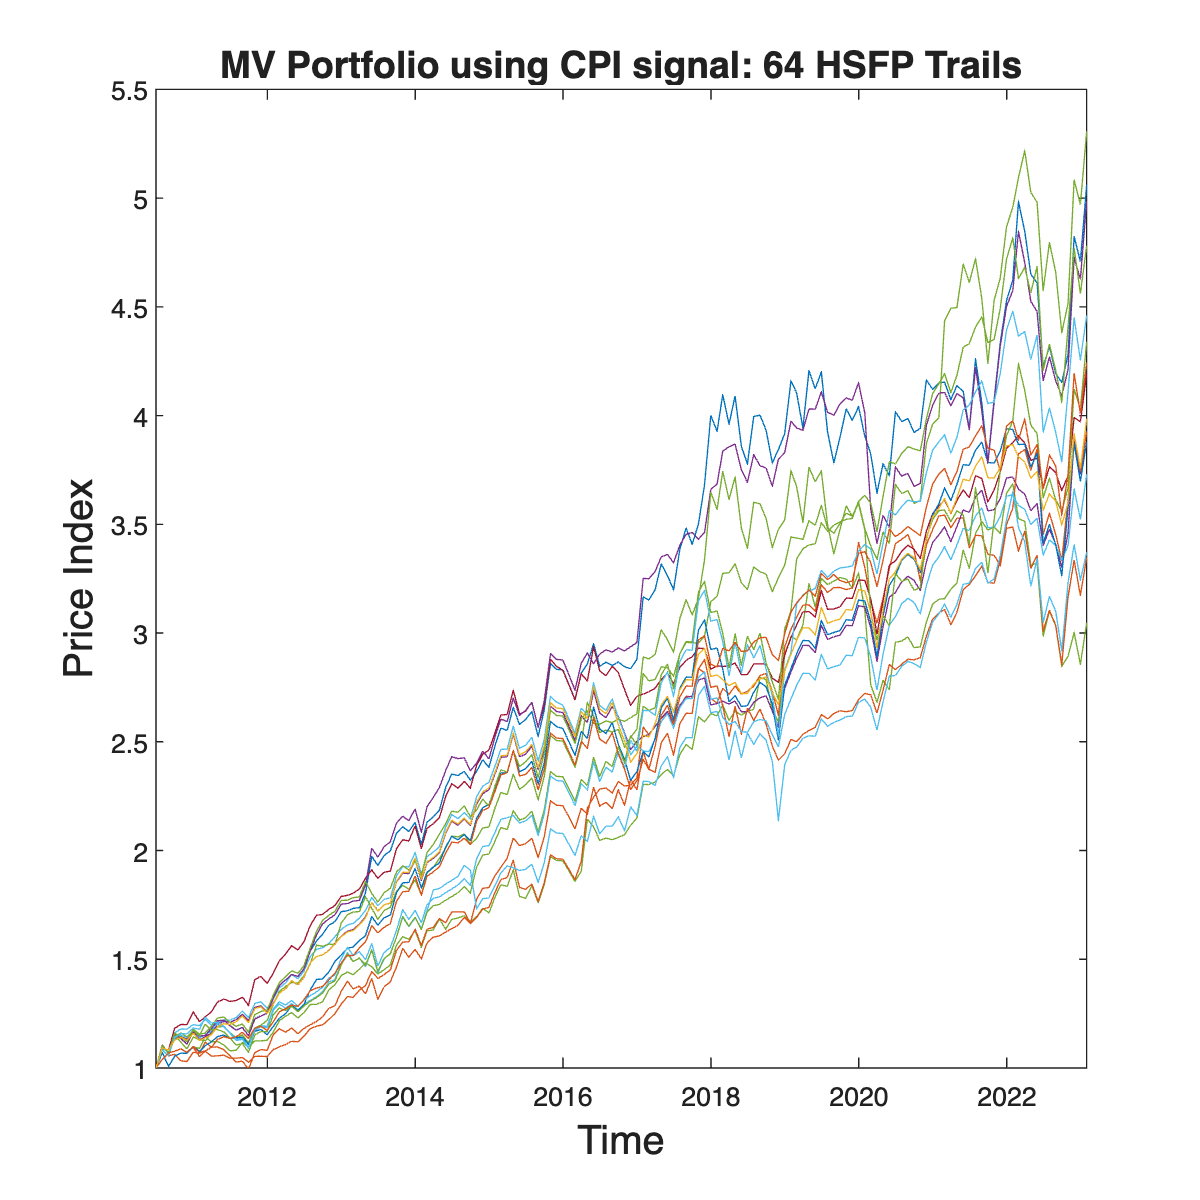

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it
for i = 1:numel(allMethods_TCpar_parameter_config_sim_cellArr)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(allMethods_TCpar_parameter_config_sim_cellArr{i}.RollingPerformance.Time, allMethods_TCpar_parameter_config_sim_cellArr{i}.RollingPerformance.("MVSR max"));  
    hold on;
end

% Customize the plot as needed
ylim([1, 5.5]);
title(['MV Portfolio using CPI signal: ',num2str(num_configs), ' HSFP Trails'],'FontSize', 14);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

MV_CPI_PARAMETER_BCKTST_SIM_Performance_plot = gcf;

% Release hold so that future plots won't overlay
hold off; 

**Export TC MV Simulations plot**

exportName = 'MV_CPI_PARAMETER_BCKTST_SIM_Performance_plot.pdf';
exportgraphics(MV_CPI_PARAMETER_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 6.2 Visualise HRP Simulations

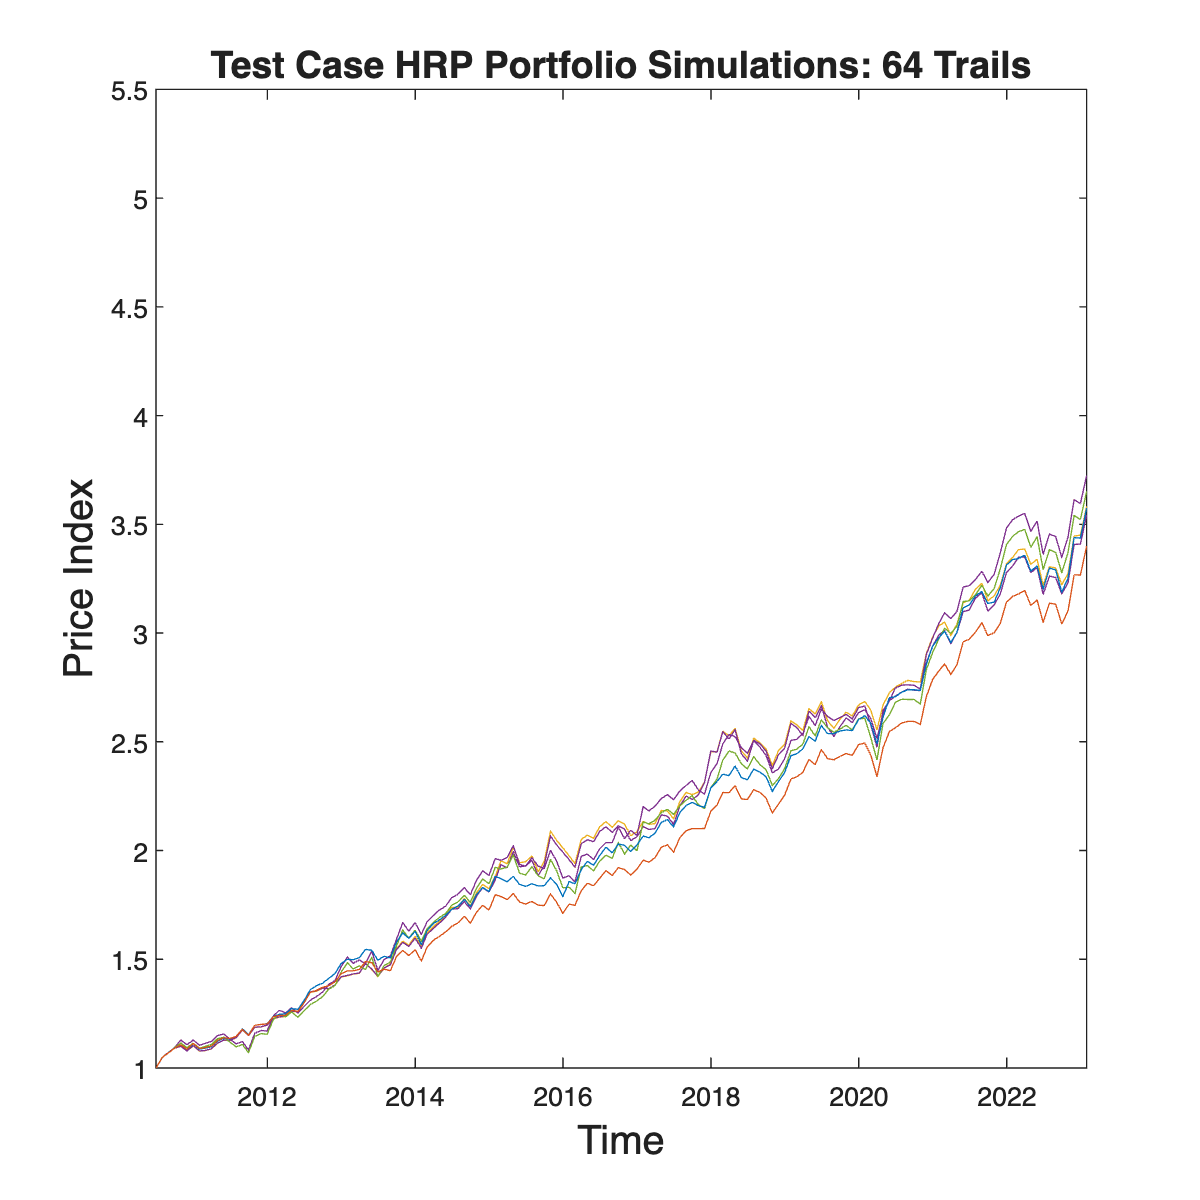

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it
for i = 1:numel(TCpar_parameter_config_sim_cellArr)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(TCpar_parameter_config_sim_cellArr{i}.RollingPerformance.Time, TCpar_parameter_config_sim_cellArr{i}.RollingPerformance.("HRP"));  
    hold on;
end

% Customize the plot as needed
ylim([1, 5.5]);
title(['HRP Portfolio using CPI signal: ',num2str(num_configs), ' HSFP Trails'],'FontSize', 14);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

HRP_CPI_PARAMETER_BCKTST_SIM_Performance_plot = gcf;


% Release hold so that future plots won't overlay
hold off; 

**Export TC MV Simulations plot**

exportName = 'HRP_CPI_PARAMETER_BCKTST_SIM_Performance_plot.pdf';
exportgraphics(HRP_CPI_PARAMETER_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',300);